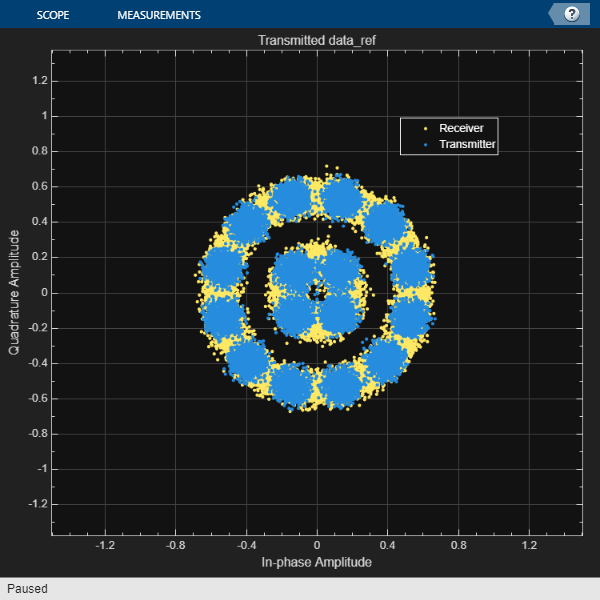

parameters;
%txOut_ref-transmitter signal
%rxIn_ref -receiver signal
[data_ref,txOut_ref,rxIn_ref,rxParams_ref]=HelperDVBS2RxInputGenerate(cfgDVBS2,simParams);
sps = cfgDVBS2.SamplesPerSymbol;


%Transmitted signal constellation plot
txConst = comm.ConstellationDiagram(Title = "Transmitted data_ref", ...
ShowReferenceConstellation = false, ...
SamplesPerSymbol = sps, ...
NumInputPorts=2, ...
ChannelNames = {"Receiver", "Transmitter"});
txConst(rxIn_ref(1:rxParams_ref.plFrameSize*sps),txOut_ref(1:rxParams_ref.plFrameSize*sps)) 

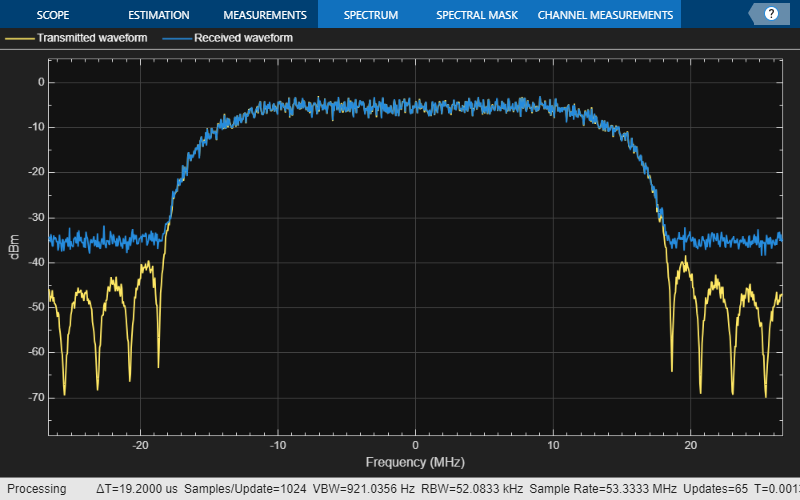


% Transmitted and received signal spectrum visualization
Rsymb = simParams.chanBW/(1 + cfgDVBS2.RolloffFactor);
Fsamp = Rsymb*simParams.sps;
specAn = spectrumAnalyzer(SampleRate = Fsamp, ...
    ChannelNames = ["Transmitted waveform" "Received waveform"], ...
    ShowLegend = true);
specAn([txOut_ref, rxIn_ref(1:length(txOut_ref))]);